%Starting/ending (year)
t0 = 0; 
tF = 50;

%timestep
h = 1/24;
time = t0:h:tF;

%Initial value of biomass at time t0 (tons)
x0 = 20;

upper_bound_for_population = 900;

%the natural growth function
syms x real
g =@(x) 0.05*(x);
sym_derr = diff(g(x));
derr_g = matlabFunction(sym_derr);


%the rate of fishing effort at time t(tons/time)
u0 = sin(time(1:end-1)); %ones(1,1 + (tF-t0)/h).*5;
%u0 = zeros(1,length(time(1:end-1)));
du0 = cos(time(1:end-1));

%the catchability coefficient(1/tons)
q = 0.0001;

%the discount rate(no unit)
rho = 0.1;

%the unit price of landed fish(money/tons)
p = 3000;

%the unit cost of effort(money/tons)
c = 1;

%derivative of x w.r.t. t
f =@(t,x,u) g(x) - q.*u.*x;

lambda_N = 0;
alpha = 1/2;
bheta = 1/2;

upperU = 900;
data.J =@(u) cost(u, f, t0, tF, x0, h, rho,c,p,q,bheta,upper_bound_for_population);
data.dJ = @(u) gr_cost(u, f, t0, tF, x0, h, rho,c,p,q, lambda_N, derr_g(), bheta,upper_bound_for_population);

data.linesearch = @(data,u,d) armijo_back(data,u,d,alpha,50,upperU); 
tol = 1e-6;
[u,opt,it,um,optm,cst] = descentmethod(data,tol,50,u0,upperU);

it=   1 J(u)= -1.350940e+03 |dJ(u)|= 2.673562e+01
it=   2 J(u)= -2.158450e+03 |dJ(u)|= 1.270762e+01
it=   3 J(u)= -2.362639e+03 |dJ(u)|= 9.190774e+00
it=   4 J(u)= -2.451057e+03 |dJ(u)|= 6.207152e+00
it=   5 J(u)= -2.494943e+03 |dJ(u)|= 5.376457e+00
it=   6 J(u)= -2.524003e+03 |dJ(u)|= 4.758028e+00
it=   7 J(u)= -2.547762e+03 |dJ(u)|= 3.670171e+00
it=   8 J(u)= -2.562261e+03 |dJ(u)|= 2.926625e+00
it=   9 J(u)= -2.571140e+03 |dJ(u)|= 2.758478e+00
it=  10 J(u)= -2.578741e+03 |dJ(u)|= 2.628819e+00
it=  11 J(u)= -2.585639e+03 |dJ(u)|= 2.475169e+00
it=  12 J(u)= -2.591820e+03 |dJ(u)|= 2.230718e+00
it=  13 J(u)= -2.596880e+03 |dJ(u)|= 1.930816e+00
it=  14 J(u)= -2.600774e+03 |dJ(u)|= 1.646158e+00
it=  15 J(u)= -2.603587e+03 |dJ(u)|= 1.380023e+00
it=  16 J(u)= -2.605578e+03 |dJ(u)|= 1.269121e+00
it=  17 J(u)= -2.607181e+03 |dJ(u)|= 1.215842e+00
it=  18 J(u)= -2.608651e+03 |dJ(u)|= 1.173430e+00
it=  19 J(u)= -2.610020e+03 |dJ(u)|= 1.133133e+00
it=  20 J(u)= -2.611297e+03 |dJ(u)|= 1.094515e+00


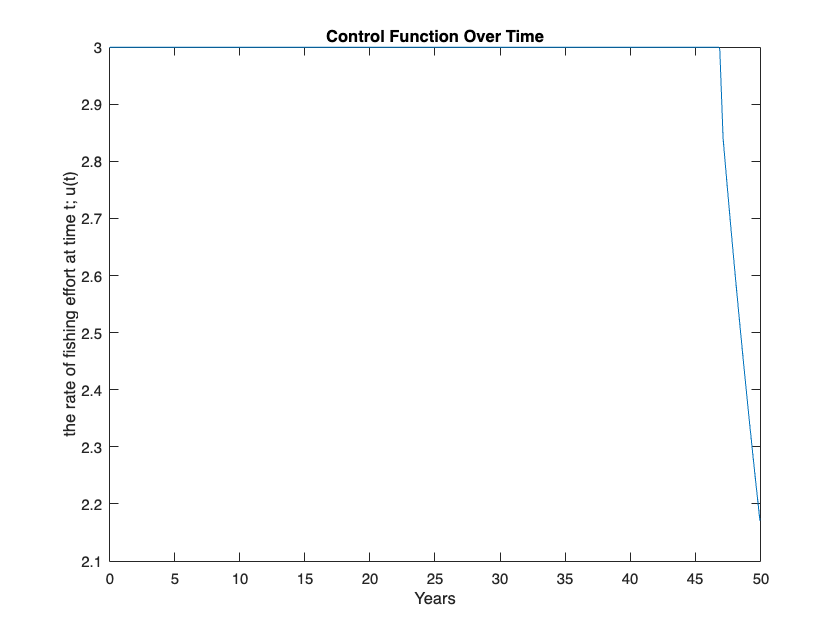


s = time(1:end-1);
plot(s,u)
title('Control Function Over Time');
xlabel('Years');
ylabel('the rate of fishing effort at time t; u(t)');

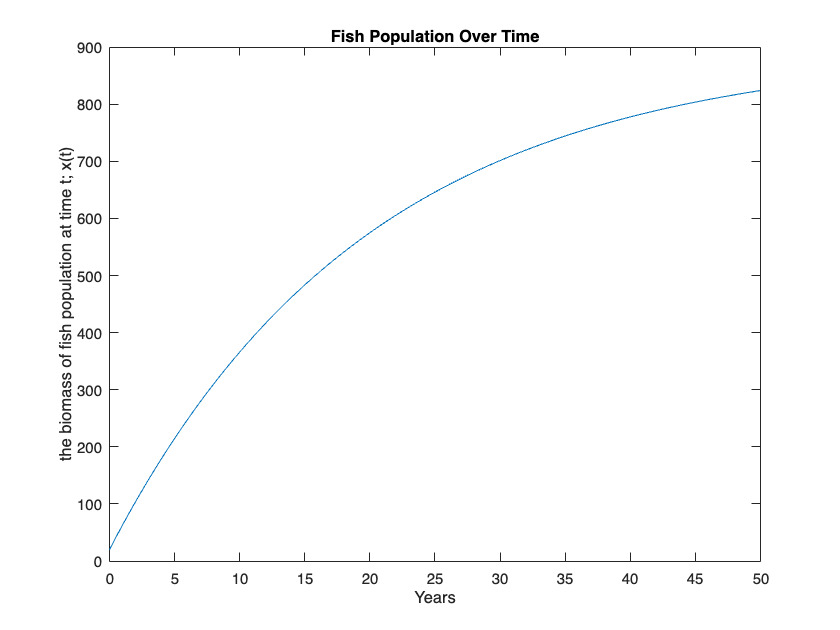


[th, uh] = explicit_euler(u, f, t0, tF, x0,  h);
plot(th,uh);
title('Fish Population Over Time');
xlabel('Years');
ylabel('the biomass of fish population at time t; x(t)');

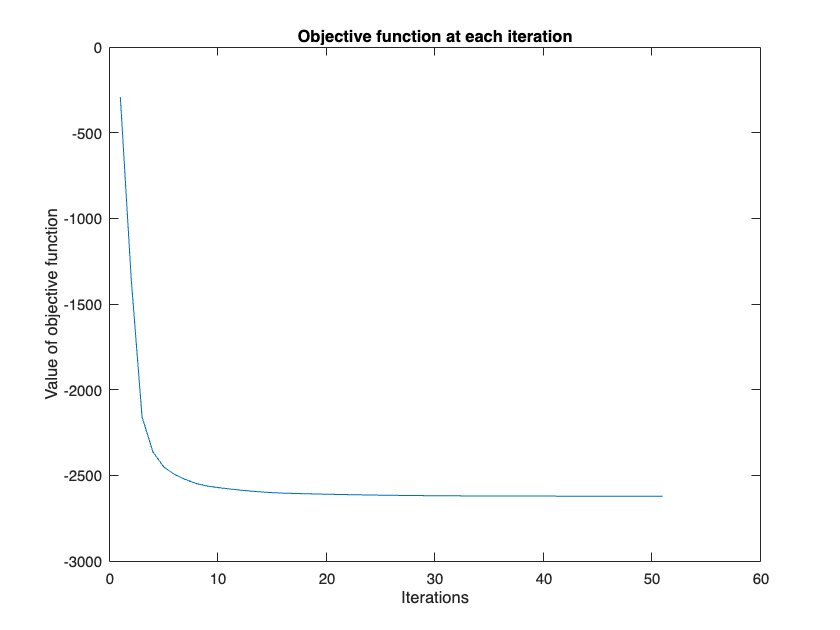


plot(cst);
title('Objective function at each iteration');
xlabel('Iterations');
ylabel('Value of objective function');

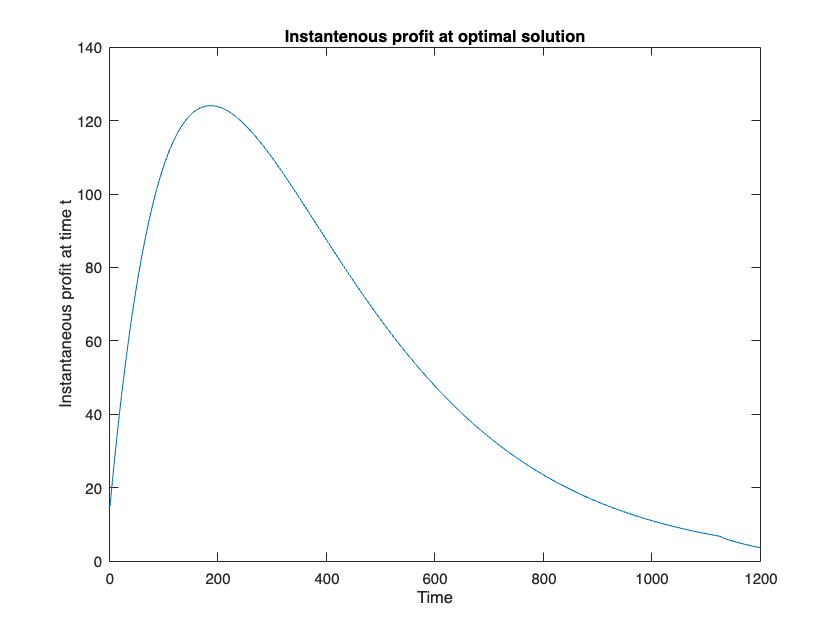


profits = profit(p, q, c, rho, th, uh, u);
plot(profits)
title('Instantenous profit at optimal solution');
xlabel('Time');
ylabel('Instantaneous profit at time t');


% Define parameter names and values
parameterNames = {'starting time (year)', 'ending time (year)', 'timestep', 'inital biomass of fish population (tons) ', 'the catchability coefficient (1/tons)', 'the discount rate', 'the unit price of landed fish (money/tons)', 'the unit cost of effort (money/tons)', 'upper bound for population', 'the natural growth function', 'alpha', 'bheta', 'upperU', 'tol'};
parameterValues = [t0, tF, h, x0, q, rho, p, c, upper_bound_for_population, g(x), alpha, bheta, upperU, tol];

% Create table
paramTable = table(parameterNames', parameterValues', 'VariableNames', {'Parameter', 'Value'})

paramTable = 14×2 table
                      Parameter                         Value  
    ______________________________________________    _________

    {'starting time (year)'                      }    0        
    {'ending time (year)'                        }    50       
    {'timestep'                                  }    1/24     
    {'inital biomass of fish population (tons) ' }    20       
    {'the catchability coefficient (1/tons)'     }    1/10000  
    {'the discount rate'                         }    1/10     
    {'the unit price of landed fish (money/tons)'}    3000     
    {'the unit cost of effort (money/tons)'      }    1        
    {'upper bound for population'                }    900      
    {'the natural growth function'               }    45 - x/20
    {'alpha'                                     }    1/2      
    {'bheta'                                     }    1/2      
    {'upper





% epsilons = [1, 0.1, 0.01, 0.001];
% values = zeros(1,length(epsilons));
% for i = 1:length(epsilons)
%     Jh_norm = cost(u0, f, t0, tF, x0, h, rho,c,p,q,upper_bound_for_population);
%     Jh_eps = cost(u0+epsilons(i).*du0, f, t0, tF, x0, h, rho,c,p,q,upper_bound_for_population);
%     gr_Jh = gr_cost(u0, f, t0, tF, x0, h, rho,c,p,q, lambda_N, derr_g(), bheta,upper_bound_for_population);
%     t_du0 = transpose(du0);
%     value = ((Jh_eps-Jh_norm)/epsilons(i)) - (gr_Jh*t_du0);
%     values(1,i) = value;
% end
% 
% loglog(epsilons,values); hold on; loglog(epsilons,epsilons); hold off;
% title('Quality of discrete gradient');
% xlabel('log(epsilon)');
% ylabel('log(error)');
% legend('log(error)','log(epsilon)');

